### (Just to see how Adaptive Quadrature works visually with Runge function.)

Function

f=@(x) 1 ./ (1 + 25 .* x .^ 2)

f = 値をもつ function_handle :
    @(x)1./(1+25.*x.^2)


To integrate function from -1 to 1

a = -1;
b = 1;
Itrue_integral = integral(f, a, b)

Itrue_integral = 0.5494

Plot original function along with simpson 1/3 rule with ns calculated from adaptive quadrature

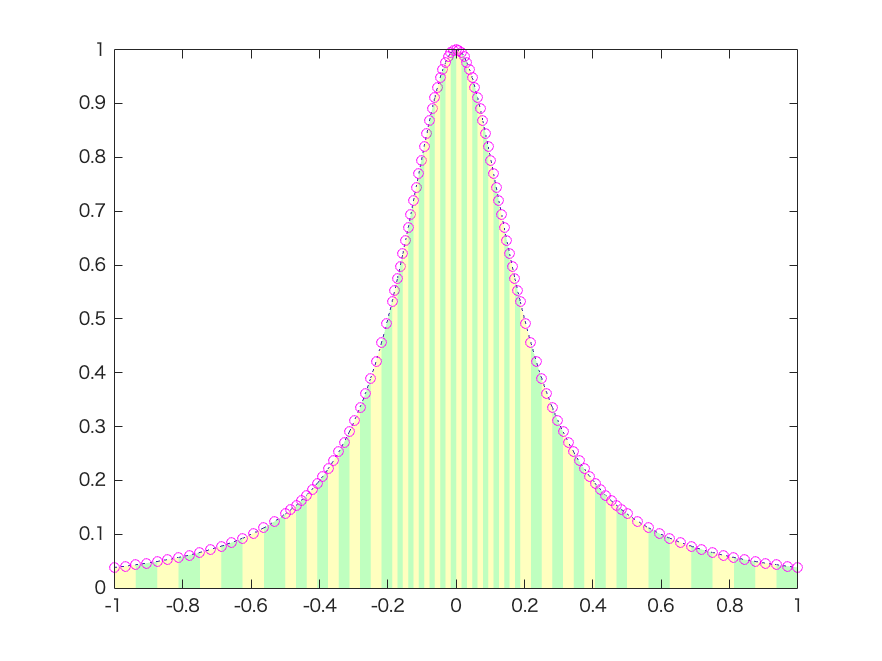

[I_quadadapt, xpts] = quadadaptWithPoints(f, a, b);

% show I_quadadapt
I_quadadapt;

% get y points
ypts = f(xpts);
% verify results
[xpts, ypts];

ns = (length(xpts) - 1) / 2;

figure
colors = ['g', 'y'];
for i = 1:ns
    ileft = 2*(i-1)+1;
    iright = 2*i+1;
    newx = xpts(ileft:iright);
    newy = ypts(ileft:iright);
    p2 = polyfit(newx, newy, 2); % we;re trying to do quadratic fitting
    xx2 = linspace(xpts(ileft), xpts(iright));
    yy2 = polyval(p2, xx2);
    area(xx2, yy2, 'FaceColor',colors(mod(i,2)+1),'FaceAlpha',0.25,'EdgeColor','flat','LineStyle',':')
    hold on
    plot(newx, newy, 'mo')
    % hold on
end